# **Control óptimo**

Un sistema de suspensión activa se puede modelar como

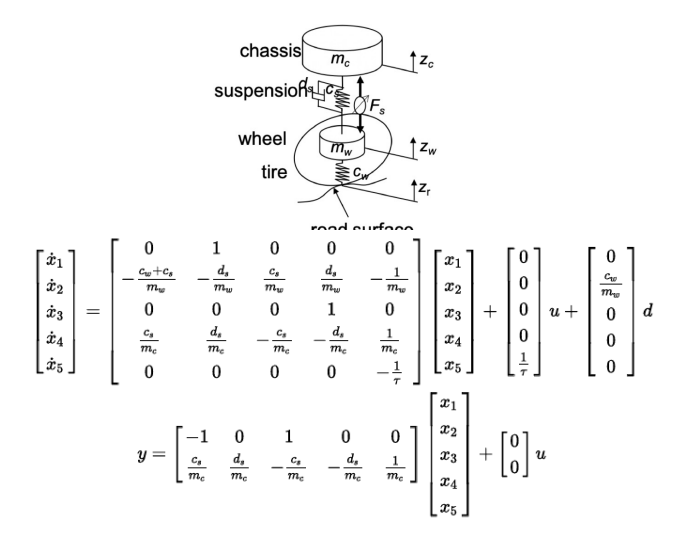

donde x1 es la posición de la rueda, x2 es la velocidad de la rueda, x3 es la posición del chasis, x4 es la velocidad del chasis y x5 es la fuerza del actuador. d es la perturbación del sistema, la posición de la superficie del terreno.

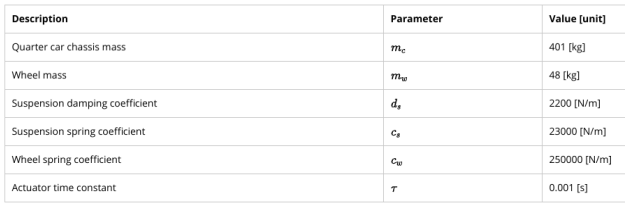

La clave en el diseño de un controlador LQR es cómo elegir los pesos Qx y Qu. Se propone encontrar una solución de compromiso entre confort al andar y estabilidad del vehículo, es decir, entre seguridad y comodidad de conducción. 

Entonces la función de costo es: 

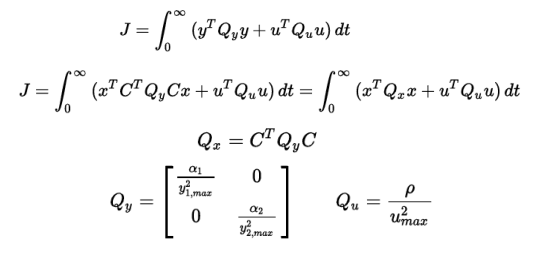

En este ejercicio, se debe diseñar un controlador de retroalimentación de estado utilizando LQR para mejorar aún más el diseño de la suspensión mediante el control activo. El controlador tendrá la forma u = −Kx ya que solo intenta reducir el impacto de la perturbación de la carretera.

Se fijan y1_max = 0,05 m, y2_max = 5 m/s^2, como la distancia entre la rueda y la aceleración del chasis; y u_max =1000 N. Estos números dan una buena relación entre desplazamiento de la suspensión y aceleración del chasis. Además, 

El modelo y los parámetros del modelo están disponibles en el archivo m Active_suspension_ctrl_design.m.

**a)** Verifique si el sistema es controlable. 

close all; clear all; clc;
% Parámetros del sistema.
mc=401;                         % Quarter car mass [kg]
mw=48;                          % Wheel mass [kg]
ds=2200;                        % Suspension damping coefficient [Ns/m]
cs=23000;                       % Suspension spring coefficient [N/m]
cw=250000;                      % Wheel spring coefficient [N/m]
tau=0.001;                      % Actuator time constant [s]
% Matrices del sistema.
A=[0            1      0      0      0;
   -(cw+cs)/mw -ds/mw  cs/mw  ds/mw -1/mw;
   0            0      0      1      0;
   cs/mc        ds/mc -cs/mc -ds/mc  1/mc;
   0            0      0      0     -1/tau];
B=[0 0 0 0 1/tau]';
H=[0 cw/mw 0 0 0]';
C=[-1    0      1      0     0;
   cs/mc ds/mc -cs/mc -ds/mc 1/mc];   
Controlabilidad = ctrb(A,B); % Matriz de controlabilidad.
r = rank(Controlabilidad,1e-10);
disp('El rango de la matriz de controlabilidad es:')

El rango de la matriz de controlabilidad es:


disp(r)

     5



disp('El sistema, por ende, es controlable.')

El sistema, por ende, es controlable.


**b)** Encuentre el valor de la matriz K para α1 =α2 =1 y ρ=1 . 

alfa_1 = 1;
alfa_2 = 1;
rho = 1;
y1_max = 0.05; % Posición máxima de la rueda.
y2_max = 5; % Aceleración máxima del chasis.
u_max = 1000;

Qy = [alfa_1/y1_max^2 0;
      0 alfa_2/y2_max^2];
Qx = C'*Qy*C;
Qu = rho/u_max^2;

[K,S,E] = lqr(A,B,Qx,Qu); % E es el vector con los polos a lazo cerrado del sistema.
disp('El vector K con las constantes de realimentación es:')

El vector K con las constantes de realimentación es:


disp(K)

   1.0e+03 *

   -3.5593    0.2450    4.8200    1.2208    0.0001



**c)** Encuentre el valor de kr. 

disp('Valor de kr:')

Valor de kr:


kr = -1/(C*inv(A-B*K)*B)

kr = 	1.0e+04 *

    3.0480         0


**d)** Utilice el modelo en Simulink provisto para analizar la respuesta del sistema a una perturbación de 5 cm al pasar por arriba de un reductor de velocidad.

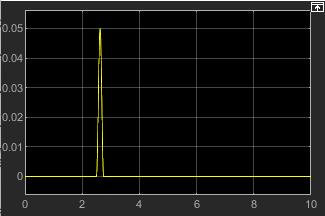

*Disturbación del camino.*

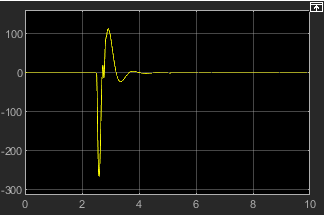

*Señal de control.*

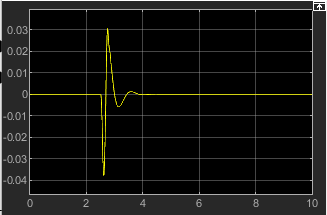

*Desplazamiento.*

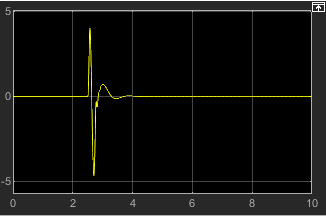

*Aceleración.*